clear all;

B_1 = 0.015;
B_2 = 0.0015;
J_1 = 0.0022;
J_2 = 0.000545;
B_3 = B_2;
J_3 = J_2;
K_s1 = 1;
K_s2 = K_s1;

k_t = 0.00767;
k_m = 0.00767;
R_m = 2.6;
nu_m = 0.69;
nu_g = 0.85;
K_gi = 14;
K_ge_low = 1;
K_ge_high = 5;
K_g = (K_gi*K_ge_low*K_ge_high);

H = nu_g*K_g*nu_m*k_t

H = 0.3149

J = K_g*k_m

J = 0.5369


theta_1_dot_const = -(H*J)/(J_1*R_m)-B_1/J_1;

A = [0 0 0 1 0 0;
     0 0 0 0 1 0;
     0 0 0 0 0 1;
     -K_s1/J_1 K_s1/J_1 0 theta_1_dot_const 0 0;
     K_s1/J_2 -(K_s1+K_s2)/J_2 K_s2/J_2 0 -B_2/J_2 0;
     0 K_s2/J_3 -K_s2/J_3 0 0 -B_3/J_3];
B = [0; 0; 0; H/(J_1*R_m); 0; 0];
C = [1 0 0 0 0 0;
     0 1 0 0 0 0;
     0 0 1 0 0 0];
D = 0;

x_0 = [0;0;0;0;0;0];

sys = ss(A, B, C, D);
Ts = 0.001;
sys_d = c2d(sys, Ts);

P_0 = eye(6);
x_kalman = [2;1;3;2;3;1];
An = sys_d.A;
Bn = sys_d.B;
Ln = [0 ; 0;0;0;0;1*Ts];
Hn = sys_d.C;
Q_n = 4000;
R_n = [1e-3 0 0;
       0 1e-3 0;
       0 0 1.7e-3];
V_m_max = 6;

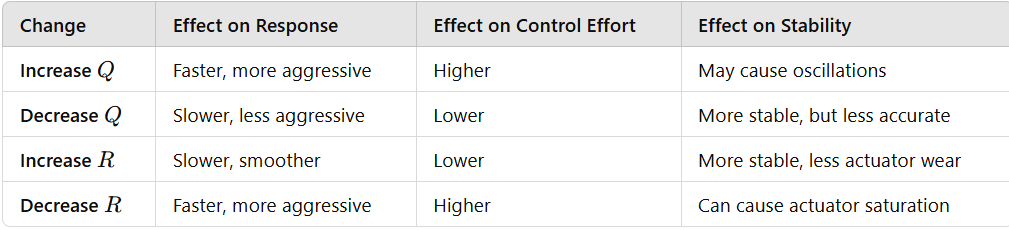

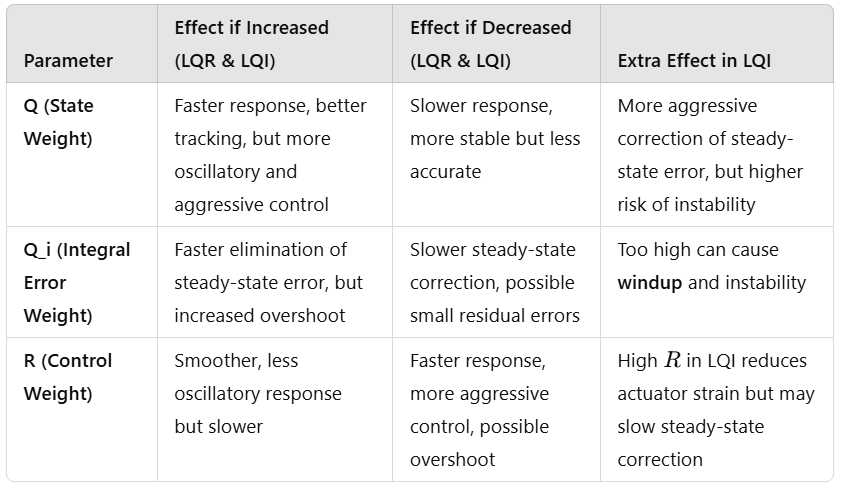

% LQR tuning using Bryson's rule:
R_lqr = 1/V_m_max^2;
Q_lqr = zeros(6,6);
Q_lqr(1,1) = 1/((0.3)^2);
Q_lqr(2,2) = 1/((0.3)^2);
Q_lqr(3,3) = 1/((0.3)^2);
Q_lqr(4,4) = 1/(5^2);
Q_lqr(5,5) = 1/((5)^2);
Q_lqr(6,6) = 1/((5)^2);

Q_lqr = 0.25*Q_lqr; % high Q faster convergance, but higher overshoot and higher actuator effort
R_lqr = 5*R_lqr; % Low R less overshoot

K_lqr = lqr(A, B, Q_lqr, R_lqr)

K_lqr =    14.7059   -7.3191    0.3592    0.3605   -0.0124    0.0954


eig(A-B*K_lqr)

ans =   -2.8446 +70.1320i
  -2.8446 -70.1320i
 -32.7654 + 0.0000i
  -9.3848 + 0.0000i
  -6.9418 +29.9914i
  -6.9418 -29.9914i


% LQI tuning:
% we have 3 more states Q_lqr = 6x6 => Q_lqi = 9x9
Q_i = diag([1/(0.5)^2, 1/(0.5)^2, 1/(0.5)^2]); % Assuming max steady-state error of 0.01m
Q_lqi = blkdiag(Q_lqr, Q_i);
Q_lqi = Q_lqi;
R_lqi = 2*R_lqr;
K_lqi = lqi(sys,Q_lqi,R_lqi)

K_lqi =    10.3484   -3.8399    0.1026    0.2604    0.0022    0.0670   -2.1909   -2.1909   -2.1909
